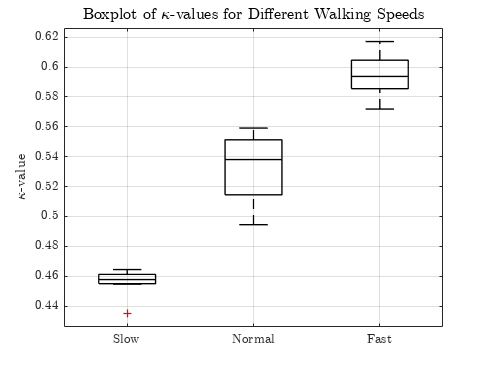

% Clear cmd window and workspace
clear
clc

% Ensure latex fontstyle
set(0,'defaulttextinterpreter','latex');

% Initialize variables for combined errors for each experiment
combined_abs_errors_slow = [];
combined_abs_errors_normal = [];
combined_abs_errors_fast = [];

% Define constants for each experiment
step_lengths = [0.6, 0.7, 0.8]; % Step lengths for slow, normal, and fast
initial_guess = 0.5; % Initial guess for k
Ts = 0.0077; % Sampling period
delta_a = 1;

experiment_names = {'slow', 'normal', 'fast'};
combined_abs_errors_all = {combined_abs_errors_slow, combined_abs_errors_normal, combined_abs_errors_fast};
k_values_all = [];

for exp_index = 1:length(experiment_names)
    % Loop through each file type (slow, normal, fast)
    for file_num = 1:10
        file_name = sprintf('tp_%s_%d.txt', experiment_names{exp_index}, file_num);

        % Read data from the file
        walking_data = dlmread(file_name, '\t'); 
        filt_data = walking_data(:,1);
        num_samples = length(filt_data);
        fs = 1/Ts; % Sampling frequency
        
        % Time parameters
        time_elapsed = Ts * num_samples;
        t = (0:Ts:time_elapsed-Ts)';
        
        [maxtab, mintab] = peakdet(filt_data, delta_a, t);
        min_rows = min(size(maxtab, 1), size(mintab, 1));
        max_points_subset = maxtab(1:min_rows, :);
        min_points_subset = mintab(1:min_rows, :);
        
        accel_diffs = max_points_subset(:, 2) - min_points_subset(:, 2);
        actual_step_length = step_lengths(exp_index);
        actual_step_lengths = actual_step_length * ones(size(accel_diffs));
        
        options = optimset('Display','off');
        [k_fit, ~, ~] = lsqcurvefit(@(k,x) k*x.^0.25, initial_guess, accel_diffs, actual_step_lengths, [], [], options);
        
        error = actual_step_lengths - (k_fit * accel_diffs.^0.25);
        absErrors = abs(error);
        
        combined_abs_errors_all{exp_index} = [combined_abs_errors_all{exp_index}; absErrors];
        k_values_all = [k_values_all; k_fit]; %#ok<AGROW>
    end
end

% Calculate mean k-value (with outliers)
k_mean = mean(k_values_all);

% Given k-values for slow, normal, and fast experiments
k_values_slow = [0.454681, 0.435097, 0.460748, 0.461213, 0.457588, 0.457965, 0.456428, 0.455018, 0.462808, 0.464474];
k_values_normal = [0.494479, 0.528023, 0.537742, 0.538444, 0.551287, 0.541740, 0.554356, 0.514469, 0.509214, 0.559170];
k_values_fast = [0.572435, 0.571893, 0.617042, 0.596328, 0.614059, 0.586243, 0.593109, 0.594328, 0.604593, 0.585527];

% Combine into a matrix for boxplot
k_values_matrix = [k_values_slow(:), k_values_normal(:), k_values_fast(:)];

% Identify and remove outliers
Q1 = quantile(k_values_matrix, 0.25);
Q3 = quantile(k_values_matrix, 0.75);
IQR = Q3 - Q1;
non_outlier_indices = ~(k_values_matrix < (Q1 - 1.5*IQR) | k_values_matrix > (Q3 + 1.5*IQR));

% Calculate mean k-value without the outliers
k_values_no_outliers = k_values_matrix(non_outlier_indices);
k_mean_no_outliers = mean(k_values_no_outliers);

% Create the boxplot in the second subplot on the right
figure;
% subplot(1, 2, 1);  % This subplot will take the left side
boxplot(k_values_matrix, 'Whisker', 1.5, 'Colors','k');
ax = gca; % Get handle to current axes
ax.TickLabelInterpreter = 'latex'; % Set the 'TickLabelInterpreter' property of the axes to 'latex'
ax.XTickLabels = {'Slow', 'Normal', 'Fast'}; % Set XTick labels with LaTeX interpreter
ylabel('$\kappa$-value', 'Interpreter', 'latex');
title('Boxplot of $\kappa$-values for Different Walking Speeds', 'FontSize', 12, 'Interpreter','latex');
set(findobj(gca,'type','line'),'linew',1) % Set line width for boxplot
grid on

% Set the figure size
fig = gcf;
fig.PaperUnits = 'centimeters';
fig.PaperPosition = [0 0 20 12]; % This will stretch the plot across an width = 21cm, height = 29.7cm
fig.PaperSize = [20 12];

% Save the figure with the specified resolution
print(fig, 'BNO085_Weinberg_Error_Boxplot', '-depsc', '-r600'); % '-depsc' is used for EPS color

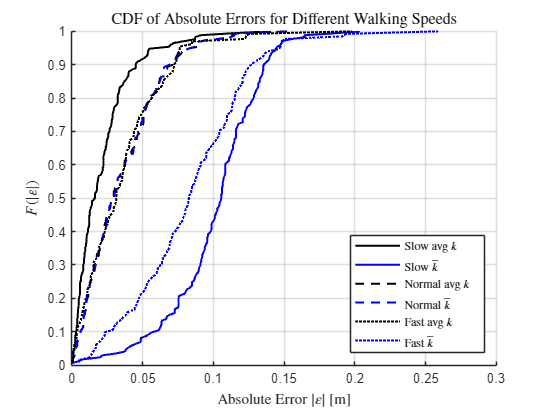


% Mark outliers with a red '+'
h_outliers = findobj(gca, 'Tag', 'Outliers');
for iOutlier = 1:length(h_outliers)
    h_outliers(iOutlier).MarkerEdgeColor = 'r';
    h_outliers(iOutlier).Marker = '+';
end

% Calculate average k-value for each speed
avg_k_values_speed = zeros(length(experiment_names), 1);
for exp_index = 1:length(experiment_names)
    % Extract k-values for this speed category
    k_values_this_speed = k_values_all((exp_index-1)*10 + (1:10));
    avg_k_values_speed(exp_index) = mean(k_values_this_speed);
end

% Initialize storage for combined errors using average k-values and k_mean_no_outliers
combined_abs_errors_avg_k = cell(length(experiment_names), 1);
combined_abs_errors_mean_k_for_speed = cell(length(experiment_names), 1);

for exp_index = 1:length(experiment_names)
    avg_k = avg_k_values_speed(exp_index);
    actual_step_length = step_lengths(exp_index);
    for file_num = 1:10
        file_name = sprintf('tp_%s_%d.txt', experiment_names{exp_index}, file_num);
        walking_data = dlmread(file_name, '\t');
        filt_data = walking_data(:,1);
        
        [maxtab, mintab] = peakdet(filt_data, delta_a, t);
        min_rows = min(size(maxtab, 1), size(mintab, 1));
        accel_diffs = maxtab(1:min_rows, 2) - mintab(1:min_rows, 2);
        
        % Errors using average k-value for this speed
        fitted_step_lengths_avg_k = avg_k * accel_diffs.^0.25;
        error_avg_k = actual_step_length * ones(size(accel_diffs)) - fitted_step_lengths_avg_k;
        combined_abs_errors_avg_k{exp_index} = [combined_abs_errors_avg_k{exp_index}; abs(error_avg_k)];
        
        % Errors using overall mean k-value for comparison
        fitted_step_lengths_mean_k = k_mean_no_outliers * accel_diffs.^0.25;
        error_mean_k = actual_step_length * ones(size(accel_diffs)) - fitted_step_lengths_mean_k;
        combined_abs_errors_mean_k_for_speed{exp_index} = [combined_abs_errors_mean_k_for_speed{exp_index}; abs(error_mean_k)];
    end
end

% Plotting
figure;
% subplot(1, 2, 2);
hold on;
% colours = {'', ''}
line_styles = {'-', '--', ':'};
for exp_index = 1:length(experiment_names)
    % Plot CDF using average k-values for each speed
    sorted_abs_errors = sort(combined_abs_errors_avg_k{exp_index});
    cdf_abs_errors = (1:length(sorted_abs_errors))' / length(sorted_abs_errors);
    plot(sorted_abs_errors, cdf_abs_errors, 'Color', 'k', 'LineStyle', line_styles{exp_index}, 'LineWidth', 1.5);
    
    % Plot CDF using mean k-value for comparison
    sorted_abs_errors_mean_k = sort(combined_abs_errors_mean_k_for_speed{exp_index});
    cdf_abs_errors_mean_k = (1:length(sorted_abs_errors_mean_k))' / length(sorted_abs_errors_mean_k);
    plot(sorted_abs_errors_mean_k, cdf_abs_errors_mean_k, 'Color', 'b', 'LineStyle', line_styles{exp_index}, 'LineWidth', 1.5);
end

xlabel('Absolute Error $|\varepsilon|$ [m]', 'Interpreter', 'latex');
ylabel('$F(|\varepsilon|)$', 'Interpreter', 'latex');
title('CDF of Absolute Errors for Different Walking Speeds', 'FontSize', 12, 'Interpreter', 'latex');
legend({'Slow avg $k$', 'Slow $\bar{k}$', 'Normal avg $k$', 'Normal $\bar{k}$','Fast avg $k$', 'Fast $\bar{k}$'}, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
hold off;

% 
% % Save the plot
% print -depsc BNO085_Weinberg_Error_CDF

function [maxtab, mintab] = peakdet(v, delta, x)
    maxtab = [];
    mintab = [];
    v = v(:);
    x = x(:);
    if length(v) ~= length(x)
        error('Input vectors v and x must have the same length');
    end
    if delta <= 0
        error('Input argument delta must be positive');
    end
    
    mn = Inf; mx = -Inf;
    mnpos = NaN; mxpos = NaN;
    lookformax = 1;
    
    for i = 1:length(v)
        this = v(i);
        if this > mx, mx = this; mxpos = x(i); end
        if this < mn, mn = this; mnpos = x(i); end
        if lookformax
            if this < mx - delta
                maxtab = [maxtab; mxpos mx]; %#ok<AGROW>
                mn = this; mnpos = x(i);
                lookformax = 0;
            end
        else
            if this > mn + delta
                mintab = [mintab; mnpos mn]; %#ok<AGROW>
                mx = this; mxpos = x(i);
                lookformax = 1;
            end
        end
    end
end

% % Plot CDF of combined absolute errors for each experiment using individual k-values
% for exp_index = 1:length(experiment_names)
%     sorted_abs_errors = sort(combined_abs_errors_all{exp_index});
%     cdf_abs_errors = (1:length(sorted_abs_errors))' / length(sorted_abs_errors);
%     plot(sorted_abs_errors, cdf_abs_errors, lineStyles{exp_index}, 'LineWidth', 1.5, 'Color', 'k');
%     hold on; % Keep the plot for adding the next experiment's CDF
% end
% 
% % Recalculate CDF of combined absolute errors using mean k-value
% combined_abs_erros_mean_k = [];
% for exp_index = 1:length(experiment_names)
%     for file_num = 1:10
%         file_name = sprintf('tp_%s_%d.txt', experiment_names{exp_index}, file_num);
%         walking_data = dlmread(file_name, '\t'); %#ok<DLMRD>
%         filt_data = walking_data(:,1);
%         
%         [maxtab, mintab] = peakdet(filt_data, delta_a, t);
%         min_rows = min(size(maxtab, 1), size(mintab, 1));
%         accel_diffs = maxtab(1:min_rows, 2) - mintab(1:min_rows, 2);
%         actual_step_length = step_lengths(exp_index);
%         actual_step_lengths = actual_step_length * ones(size(accel_diffs));
%         
%         fitted_step_lengths = k_mean_no_outliers * accel_diffs.^0.25;
%         error = actual_step_lengths - fitted_step_lengths;
%         absErrors = abs(error);
%         
%         combined_abs_erros_mean_k = [combined_abs_erros_mean_k; absErrors]; %#ok<AGROW>
%     end
% end

% % Add the CDF plot for mean k-value
% sortedAbsErrorsMeanK = sort(combined_abs_erros_mean_k);
% cdfAbsErrorsMeanK = (1:length(sortedAbsErrorsMeanK))' / length(sortedAbsErrorsMeanK);
% plot(sortedAbsErrorsMeanK, cdfAbsErrorsMeanK, 'LineWidth', 1.5, 'Color', 'b');
% xlabel('Absolute Error $|\varepsilon|$ [m]', 'Interpreter', 'latex');
% ylabel('$F(|\varepsilon|)$', 'Interpreter', 'latex');
% title('CDF of Fitted $\kappa$-values vs. $\bar{\kappa}$-value for Different Walking Speeds', 'FontSize', 12, 'Interpreter', 'latex');
% legend('Slow', 'Normal', 'Fast', '$\bar{\kappa} = 0.5309$', 'Interpreter', 'latex', 'Location', 'southeast');
% grid minor;
% hold off;